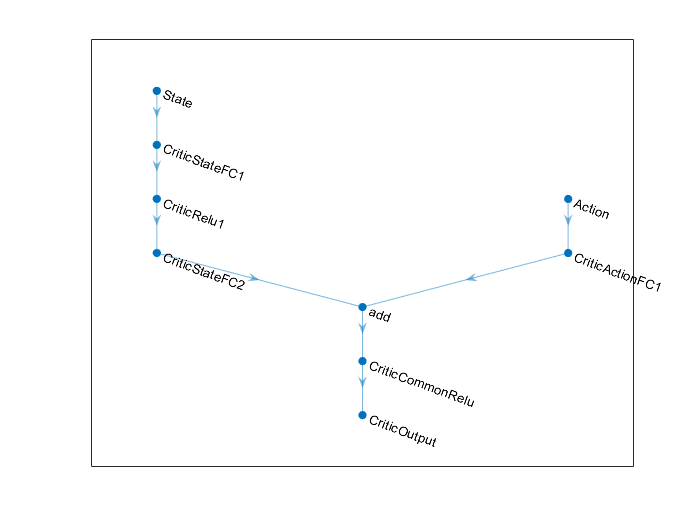

clc;clear; close all;
open_system('solar_48vBattery.slx')
obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf 0  ]',...
    'UpperLimit',[ inf inf inf ]');
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'flow';
numActions = actInfo.Dimension(1);
env = rlSimulinkEnv('solar_48vBattery','solar_48vBattery/RL Agent',...
    obsInfo,actInfo);
env.ResetFcn = @(in)localResetFcn(in);
Ts = 1;
Tf = 1;
rng(0)
statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(300,'Name','CriticStateFC1')
    eluLayer('Name','CriticRelu1')
    
    %fullyConnectedLayer(100,'Name','CriticStateFC1')
    %reluLayer('Name','CriticRelu1')
    %fullyConnectedLayer(200,'Name','CriticStateFC2')
    %reluLayer('Name','CriticRelu2')
    %fullyConnectedLayer(100,'Name','CriticStateFC3')];

    fullyConnectedLayer(150,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    %fullyConnectedLayer(150,'Name','CriticActionFC1')];
    fullyConnectedLayer(150,'Name','CriticActionFC1')];

commonPath = [
    additionLayer(2,'Name','add')
    eluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')
    %reluLayer('Name','CriticCommonRelu') 
    ];
    

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
figure
plot(criticNetwork)

criticOpts = rlRepresentationOptions('LearnRate', 1e-04, 'GradientThreshold',1);
critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);
actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action2')
    %eluLayer('Name','Action')
    sigmoidLayer('Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-05,'GradientThreshold',1);

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

Z =   1×1 single dlarray

    0.7311


Z =   1×1 single dlarray

    0.7311


Z =   1×1 single dlarray

    0.7311


agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',0.1, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;
agent = rlDDPGAgent(actor,critic,agentOpts);
maxepisodes = 500;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',800);
doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);

end

Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.6171


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.2710


simOpts = rlSimulationOptions('MaxSteps', maxsteps, 'StopOnError','on');
experiences = sim(env,agent,simOpts);

Z =   1×1 single dlarray

    0.2710


Z =   1×1 single dlarray

    0.1748


function in = localResetFcn(in)

blk = sprintf('solar_48vBattery/Desired');
h = 315.234;
in = setBlockParameter(in,blk,'Value',num2str(h));


end
